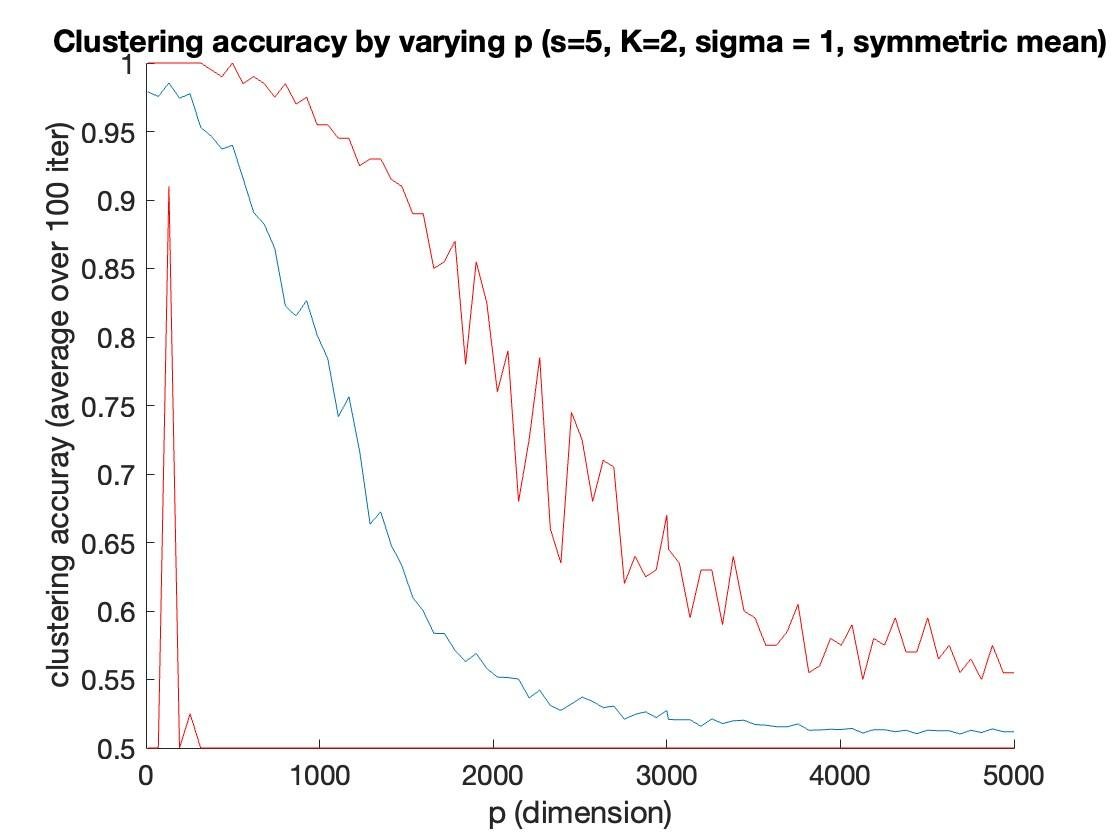

iterative thresholding

1. run  SDP k-means. re-arrange the rows to get $X_{{\mathcal{G}}_1}$and $X_{{\mathcal{G}}_2}$.

2. Calculate group sample means:

                
$$\bar{X}_{{\mathcal{G}}1} := {n{{\mathcal{G}}_1}}^{-1} 1^\top X{{\mathcal{G}}_1}
\\
\bar{X}_{{\mathcal{G}}_2} := {n{{\mathcal{G}}_2}}^{-1} 1^\top X{{\mathcal{G}}_2}$$


3. guess the non-zero entries: make a zero-one vectors by thresholding each element of the group sample mean by


$$ c_1 = \sigma \sqrt{ \frac{2 \log p}{{n_{{\mathcal{G}}1}}}}, \quad c_2 = \sigma \sqrt{\frac{2 \log p}{{n_{{\mathcal{G}}_2}}}} $$


4. Apply thresholding to the data matrix (not affinity matrix)

5. Run SDP k-means to the thresholded data

6. iterate 2-5.

n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 3; 

sep =5;
s = 10;
M = sqrt(sep^2 / 4 / s);

p_start = 10;
p_end = 15000;
n_grid = 2000;
p_vec =  [round(linspace(p_start, p_end, n_grid))];
n_rep = 100;

n_pararell = 10;
n_p_chunk = n_grid/n_pararell;
p_vec_chunk = {};
clustering_acc_mat_chunk = {};

for i = 1:n_pararell
    p_vec_chunk{i} = p_vec( ((i-1)* n_p_chunk + 1) : (i*n_p_chunk) );
    clustering_acc_mat_chunk{i} = repmat( repelem(0, n_p_chunk ), n_rep, 1 );
end


parpool('Processes')

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 12
                 Busy: false
              Cluster: 

tic
% parallel for loop
parfor w = 1 : n_pararell
%
    for i = 1:length(p_vec_chunk{w})
    p = p_vec_chunk{w}(i)
    sparse_mean = [repelem(1,s), repelem(0,p-s)];
    mu_1 =  -M * sparse_mean;
    mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);
    
    for j = 1:n_rep
        
    %data generation
        x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
        A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
        x_now = x;
        A_now = (x_now * x_now')/ n;
        Z_now = kmeans_sdp(A_now, K);     
        cluster_est_now = estimate_cluster(Z_now, rounding, n, cluster_true);
        cluster_acc_before_thres = max( ...
            mean(cluster_true ==  cluster_est_now), ...
            mean(cluster_true == -cluster_est_now) ...
            );
        %fprintf("p = %i, acc before thres: %f", p, cluster_acc_before_thres);
    
        % iterate
 
        clustering_acc_mat_chunk{w}(j, i) = iterative_kmeans(x, sigma, K, p, n_iter, rounding, n, cluster_true);
    end
end
end

Error using svec
Use of MEX functions is not supported on a thread-based worker.

Error in kmeans_sdp (line 45)
Auxt(:,1)=svec(blk(1,:), eye(n),1);

toc


clustering_acc_mat = [];


clustering_acc_mat =

     []



for i = 1:n_pararell
    clustering_acc_mat = [clustering_acc_mat, clustering_acc_mat_chunk{i}];
    x = p_vec;                     
    y = mean(clustering_acc_mat,1);
    y_max = max(clustering_acc_mat);
    y_min = min(clustering_acc_mat);
end

clustering_acc_mat =     0.9850    0.9850    0.9950
    0.9950    0.9950    1.0000


clustering_acc_mat =     0.9850    0.9850    0.9950    1.0000    0.9950    0.9850
    0.9950    0.9950    1.0000    0.9800    0.9850    0.9850


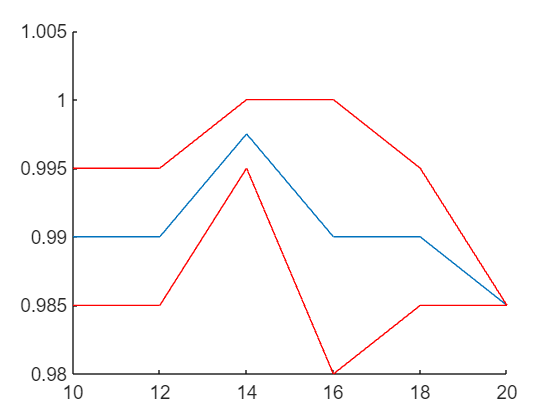


figure;
         

hold on
plot(x,y)
plot(x,y_max,'red')
plot(x,y_min,'red')
hold off